# ==Wave Parameter Extraction Pipeline

This MATLAB LiveScript serves as a live document to show the implementation of the SAR wave parameter extraction pipeline with additional documentation. Documentation notes are included before code blocks which explain the code which follows.

## Obtain SAR Data

[https://earth.esa.int/eogateway/documents/20142/37627/COSMO-SkyMed-Second-Generation-Mission-Products-Description.pdf](https://earth.esa.int/eogateway/documents/20142/37627/COSMO-SkyMed-Second-Generation-Mission-Products-Description.pdf)

## **Pre-Process SAR Data**

Open CosmoSkyMED image in SNAP:

- Subset image

- Save as .nc file

****TO DO:** Remove the need for this step

## 0 Import Libraries

waveFunctions = waveFunctions;
handh = hAndH1991Library;
transectFunctions = transectFunctions;
plotFunctions = plotFunctions;

## 1 Import the CosmoSkyMED Data

***** TO DO: look at calculating the satellite velocity from the metadata rather than hardcoding? (see Ryan's 4022 comments on the Sentinel data - pg.48)***

### 1.1 Import from file

After exporting the SAR data as a NetCDF file, use the following commands to import the data and metadata into MATLAB.

filepath = "/Users/tris/Documents/MATLAB/MSc/subset_CSKS1_DGM_B_WR_01_VV_RA_SF_20220722070221_20220722070237_small.nc";

% Import metadata information for ease of figuring out where everything is
% stored (this is just a dev step)
ncInfo_SAR = ncinfo(filepath);
% Create a cosmo satellite object to store all important information.
cosmo = CosmoSkyMED(filepath,"CSK");

% Import general SAR parameters.
sar_scene_orientation_angle = cosmo.SceneOrientationAngle; % Angle offset of the SAR image to North
% IN Sentinel this is called the "centre_heading" and "centre_heading2"

sar_azimuth_to_north_angle = cosmo.azimuthToNorthAngleConversion;
sar_dy = cosmo.AzimuthResolution;
sar_dx = cosmo.RangeResolution;
sar_start_datetime = cosmo.AcquisitionStartDatetime;
sar_stop_datetime = cosmo.AcquisitionStopDatetime;

% Import the SAR data.
sar_latGrid = cosmo.getLatitudeGrid;
sar_lonGrid = cosmo.getLongitudeGrid;
sar_Data_uncalibrated = (cosmo.getSARImageAmplitude)';
sar_Data_uncalibrated = sar_Data_uncalibrated/mean(sar_Data_uncalibrated(:)); % Normalise the intensity values to a value between 0 and 1.

Alternatively, import the data as an hdf5 file.

% filepath = "/Users/tris/Documents/MATLAB/MSc/20220722_1778608_CSG_/CSG_SSAR1_DGM_B_0301_SC1_001_VV_RA_F_20220722065043_20220722065057_1_F_57S_Z31_N00.h5";
%
% h5Info = h5info(filepath);
%
% % Create a structure to store imported HDF5 data
% sarData = h5read(filepath, '/IMG');
% % Display results
% figure; imshow(sarData);

### 1.2 View Original SAR Data

Choose whether to display a image of the imported SAR data.

% plotSARData = true;
% figure;
% pcolor(sar_Data_uncalibrated.^2);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% title("COSMO-SkyMed (X-band) No Cal SAR image - 22/07/2022")
% ylabel("Across Range Pixels");
% xlabel("Along Range Pixels");

### 1.3 Radiometric Calibration

sar_Data = cosmo.getRadiometricallyCalibratedImage()';
sar_Data = sar_Data/mean(sar_Data(:)); % Normalise the intensity values to a value between 0 and 1.

% plotSARData = true;
% figure;
% pcolor(sar_Data);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% title("COSMO-SkyMed (X-band) Calibrated SAR image - 22/07/2022")
% ylabel("Across Range Pixels");
% xlabel("Along Range Pixels");

% figure;
% pcolor(sar_lonGrid,sar_latGrid,sar_Data);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% title("COSMO-SkyMed (X-band) Calibrated SAR image - 22/07/2022")
% ylabel("Latitude");
% xlabel("Longitude");

% figure;
% pcolor(sar_Data);
% shading("flat");
% colormap("gray");
% clim([0 2]);

Clear vars

clear sar_Data_uncalibrated;

## 2 Open Ocean Transect

This transect needs to be absent of any ice i.e. completely open ocean.

****TO DO**: Come up with a smart way of doing open ocean detection when selecting the first transect. 

sar_transect_size = 512; % This is the standard size used.
sar_sub_transect_size = 128;

### **2.1 Define Points of Interest / Transect**

These are the top left corner point of the OO transect.

latitude_of_interest = -58.59;
longitude_of_interest = -1.1;

### 2.2 Create the OO Transect

Now we need to find the indexes. Note that in matlab dimension are row by columns = y by x = latitude by longitude

sar_transect_lat_start_index = find(floor(sar_latGrid(:,1)*100)/100 == latitude_of_interest);
sar_transect_lat_end_index = sar_transect_lat_start_index - sar_transect_size +1;

sar_transect_lon_start_index = find(floor(sar_lonGrid(sar_transect_lat_start_index(1),:)*100)/100==longitude_of_interest);
sar_transect_lon_end_index = sar_transect_lon_start_index + sar_transect_size -1;

sar_transect = sar_Data(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1));
sar_transect_lonGrid = sar_lonGrid(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1));
sar_transect_latGrid = sar_latGrid(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1));

% 
% % Plot the transect on the original image
% figure;
% pcolor(sar_lonGrid, sar_latGrid, sar_Data);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% hold on;
% pcolor(sar_transect_lonGrid,sar_transect_latGrid,sar_transect);
% hold off;

% % Plot the transect
% figure;
% pcolor(sar_transect_lonGrid, sar_transect_latGrid, sar_transect);
% shading("flat");
% colormap("gray");
% clim([0 2]);

### 2.3 Update the latitudes and longitudes

start_latitude= sar_transect_latGrid(1,1);
stop_latitude= sar_transect_latGrid(sar_transect_size,sar_transect_size);
start_longitude = sar_transect_lonGrid(1,1);
stop_longitude = sar_transect_lonGrid(sar_transect_size,sar_transect_size);

Clear variables

clear sar_latGrid; clear sar_lonGrid; clear sar_Data;

## 3 ERA5 Data

This is wave model data. We need to subdivide it to get the matching time, date, lattitudes and longitudes of our SAR data. The larger data then also needs to be sliced so that we can get the data matching the OO transect.

Finally, we need to calculate or use the mean wave direction so that are able to subdivide the SAR image into transects that flow into the ice.

### 3.1 Download

Get this from the CDS_ERA5_datahandling.mlx script. ****TO DO**: Make it adjustable so that the correct date and time data can be downloaded.

### 3.2 Import the data from the file

The data needs to be 'decoded' according to the ERA5 documentation:  [https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation](https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation)

Specifically:

"

The NetCDF wave spectra file will have the dimensions longitude, latitude, direction, frequency and time.

However, the direction and frequency bins are simply given as 1 to 24 and 1 to 30, respectively.

The **direction bins** start at 7.5 degree and increase by 15 degrees until 352.5, with 90 degree being towards the east (Oceanographic convention).

The **frequency bins** are non-linearly spaced. The first bin is 0.03453 Hz and the following bins are: f(n) = f(n-1)*1.1; n=2,30. 

The data provided is the log10 of spectra density. To obtain the spectral density one has to take to the power 10 (10 ** data). This will give the units 2D wave spectra as m**2 s radian**-1 . Very small values are discarded and set as missing values. These are essentially 0 m**2 s radian**-1.

This recoding can be done with the Python [xarray](http://xarray.pydata.org/en/stable/) package, for example:

**Units of 2D wave spectra**

Once decoded, the units of 2D wave spectra are m2 s radian-1

"

%% Get Parameters of the complete
filepath = "/Users/tris/Documents/MSc/ice-SAR-pipeline/software/SCALE_ERA5-2Dws_20220722.nc";

% Store file info in MATLAB struct
ncinfo_era5 = ncinfo(filepath);

era5 = ERA5(filepath);

% Get attributes
era5_lon = era5.getLongitude;
era5_lat = era5.getLatitude;
era5_time = era5.getTime;
% era5_d2fd_all_5dims = era5.getAllWaveSpectrumD2FD; 

era5_freq_bins = era5.FrequencyBins;

era5_direction_bins_original_degrees = era5.DirectionBins;

### **3.3 Get the Wave spectrum at similar points to SAR data**

#### **3.3.1 Find the longitude and latitudes that are the closest to the SAR transect**

****TO DO: Need to figure out how to find the matching lat and long positions (round, floor or ceil? based on the first or last pixel location?) - future me: based on center I think since this is how we calc incidence angle, slant range and transects.**

****TO DO: ADD evaluation for spectrum selected (if the closest point in the lat lon match is in the ice then check the next option).**

clear era5_d2fd;
[era5_d2fd, lat_match_index, lon_match_index, time_match_index] = era5.getSlicedWaveSpectrumD2Fd(start_latitude,start_longitude,sar_start_datetime);
% lat = era5_lat(lat_match_index);
% lon = era5_lon(lon_match_index);
% time = era5_time(time_match_index);

### 3.4 Adjust the Spectrum to match the SAR scene geometry

We need to then adjust the wave spectrum so that it is oriented the same as the SAR scene orientation

% We need to rotate the wave spectrum so that it is aligned with the angle
% at which the SAR data has been taken.
era5_direction_bins_degrees = era5.getDirectionsInSARGeometry(sar_azimuth_to_north_angle);

Plot the data before and after being adjusted

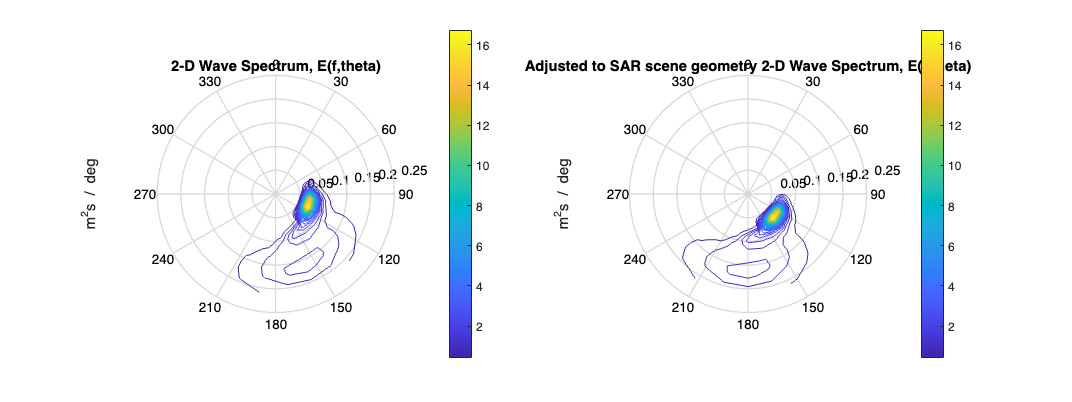

figure('Position', [100, 100, 800, 300]);
subplot(1,2,1);
PolarContour(era5_d2fd, era5_freq_bins, 0.23, era5_direction_bins_original_degrees, 40); % ADD AZ AND RANGE AXIS LABELS
title("2-D Wave Spectrum, E(f,theta)");
% TO DO: Reformat to  -> 360 and add lines for every 30 degrees
subplot(1,2,2);
PolarContour(era5_d2fd, era5_freq_bins, 0.23, era5_direction_bins_degrees, 40); % ADD AZ AND RANGE AXIS LABELS
title("Adjusted to SAR scene geometry 2-D Wave Spectrum, E(f,theta)");

### **3.5 Plot the 2D wave spectra**

Note when working with the data: the dimensions are usually in the order lon lat time OR lon lat dir frq time. This can be checked by using ncinfo to get a structure of the file and then looking at the "Dimensions" field.

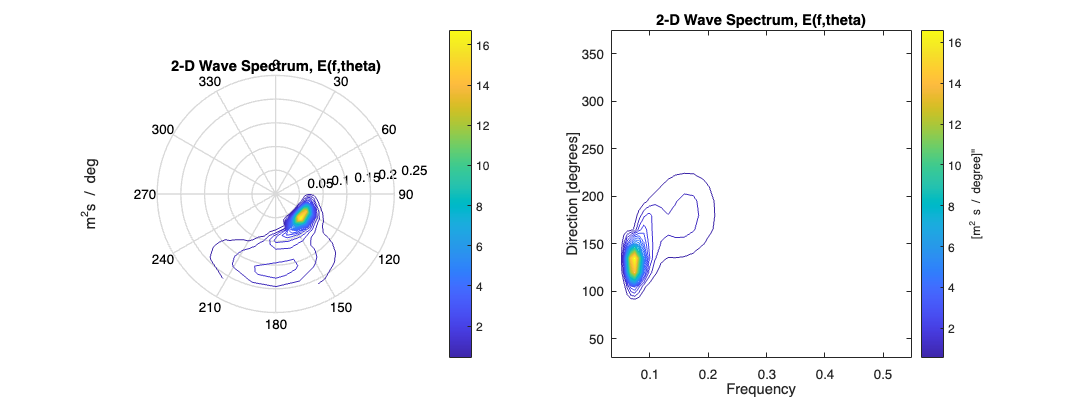

plotERA52Dspectrum = true;
if plotERA52Dspectrum
    % Plot the 2D spectra
    figure('Position', [100, 100, 800, 300]);
    subplot(1,2,1);
    PolarContour(era5_d2fd, era5_freq_bins, 0.23, era5_direction_bins_degrees, 40); % ADD AZ AND RANGE AXIS LABELS
    title("2-D Wave Spectrum, E(f,theta)")
    % TO DO: Reformat to  -> 360 and add lines for every 30 degrees
    subplot(1,2,2);
    contour(era5_freq_bins,era5_direction_bins_degrees,era5_d2fd,30);
    xlabel("Frequency"); ylabel('Direction [degrees]');title("2-D Wave Spectrum, E(f,theta)"); c = colorbar();c.Label.String = '[m^2 s / degree]"';
end

# Open Ocean H&H

## 1 First guess wave number spectrum

*This is derived from the Directional Wave Buoy (ERA5) Wave Spectrum data.*

- *You need to orient the wave spectrum to the SAR image angle. The SAR image is taken at a certain angle to the North (this angle can be found in the metadata). The ERA wave spectrum needs to be rotated so that it is inline with this. This is done earlier in the code when the data is imported by adding this angle to the direction bins of the ERA5 data. THis is a very important sstep as you need to orient the real spatial data in temrs of the SAR geometry. This angle can also clearly be seen when viewing the SAR image plots (the plot where the longitude and latittude axes are added vs the plot where they are not).*

- *Then we need to calculate the ****wave number spectrum**** from the E(f, theta). Note here that the ERA data is given in E(f,theta) but the Holthuijsen formula requires E(w,theta). To obtain this we need E(w, theta) = 2 pi E(f, theta). Holthuijsen is used as the reference for this BUT also investigate the Dynamics and Modeling of Ocean Waves (recommended by Giacomo).*

- **Note: The wave number spectrum is the projection of the wave spectrum (f,theta) into the wavenumber (kx,ky) domain.** **"**Where the wave spectrum considers the sea as a function of space and time, η(x, y, t), the ocean can also be considered as a function of space at a single moment in time. This idea is useful for remote sensing applications."  "The wave-number spectrum, E(kx,ky) is useful for remote sensing applications, and the frequency-direction spectrum, E(f,θ), is used for wave models"  (Ryan 4022). pg 20-21

- This needs to be a plot of the ERA5 d2fd data on a kx ky grid. See the comments below but need to look at how it is done in Holthuijsen.

- Make the plot and then compare to the HH paper. Plot next to the f theta plot to see the difference and the translation.

### 1.1 Parameter Calculations / Instantiation

gravity = 9.81;

### **1.2 Wave Number Spectrum Function**

**Holthuisen** states that "*"Remote-sensing *and numerical wave models can estimate the full two-dimensional spectrum, usually the wave-number spectrum *E *(*k x *, *k y *)" [pg.52 Holthuijsen]. So we now need to calculate the wave number spectrum

era5_omega = 2 * pi * era5_freq_bins; % Angular velocity, omega = 2pi * frequency; also calculated as era5_omega = sqrt(gravity .* era5_k)

era5_k = (era5_omega).^2 ./ gravity; % from deep water approximation of omega = sqrt(gk), [Eq.5.4.18 Holthuijsen]

[era5_wave_number_spectrum, Jacobian, era5_kx_matrix,era5_ky_matrix] = waveNumberSpectrum(era5_d2fd,era5_omega,era5_k, era5_direction_bins_degrees);

#### 1.2.1 Plot Wave Number Spectra, E(k) with E(f,theta)

% figure('Position', [100, 100, 800, 300]);
% subplot(1,3,1);
% contour(era5_freq_bins,era5_direction_bins_degrees,era5_d2fd,40);
% xlabel("Frequency"); ylabel('Direction [degrees]');title("2-D Wave Spectrum, E(f,theta)"); colorbar;
% subplot(1,3,2);
% contour(era5_kx_matrix, era5_ky_matrix, era5_wave_number_spectrum,40);
% xlabel("k_x"); ylabel('k_y');title("2-D Wave number Spectrum, E(k_x,k_y)")
% xlim([-0.05 0.05]); ylim([-0.05 0.05]); c = colorbar();c.Label.String = '[units?]';
% % Check that the number spectrum was calculated correctly: we should be
% % able to calculate the original energy from the wave number spectrum.
% isequal(era5_E_kx_ky(5,5)/scaling_factor(5), era5_d2fd(5,5))

### 1.3 Interpolation of the spectrum

The original ERA5 data is in a 24x30 grid format, however the SAR transect is 512x512 pixels. For this reason the original ERA5 data is extrapolated into a 512x512 grid.

[interp_E_kx_ky,interp_kx_matrix,interp_ky_matrix] = interpolateWaveNumberSpectrum(sar_sub_transect_size,sar_dx, sar_dy, era5_wave_number_spectrum, era5_kx_matrix, era5_ky_matrix);
interp_k_matrix = sqrt(interp_kx_matrix.^2 + interp_ky_matrix.^2);

#### 1.3.1 Plot wave number spectrum

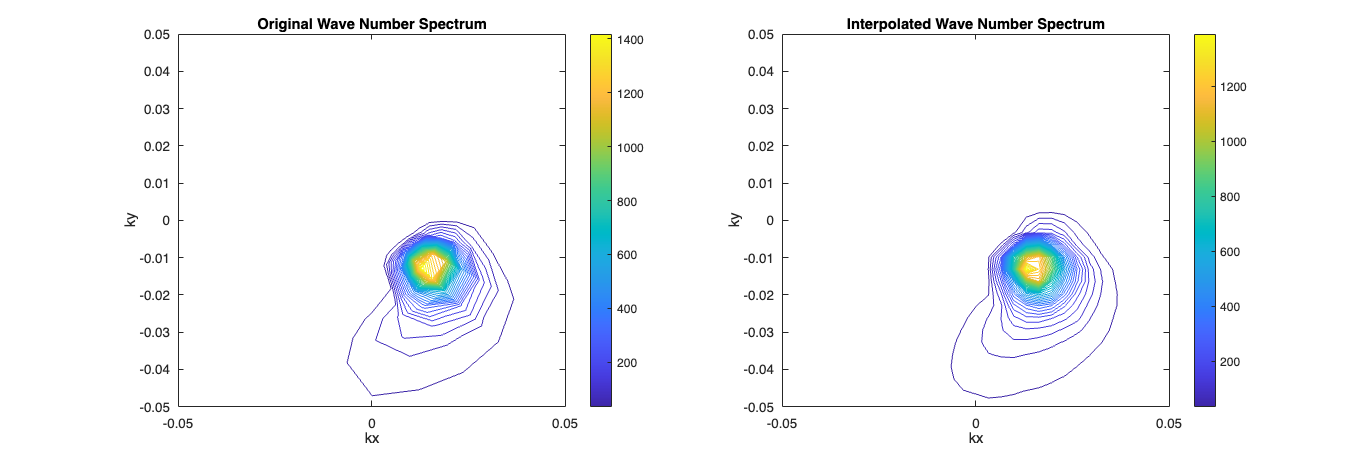

figure('Position', [200, 200, 1200, 400]);
subplot(1,2,1); contour(era5_kx_matrix,era5_ky_matrix,era5_wave_number_spectrum,40);
xlim([-0.05 0.05]); ylim([-0.05 0.05]); colorbar;
xlabel("kx"); ylabel("ky"); title("Original Wave Number Spectrum");
subplot(1,2,2); contour(interp_kx_matrix,interp_ky_matrix,interp_E_kx_ky,40);
xlim([-0.05 0.05]); ylim([-0.05 0.05]); colorbar;
xlabel("kx"); ylabel("ky");title("Interpolated Wave Number Spectrum");

#### 1.3.2 Plot parameters (E, k , kx & ky) before and after interpolation

% My attempt at understanding what is going on:
% figure('Position', [0, 0, 1600, 900]);
% subplot(3,4,1)
% plot(era5_k);
% title("ERA5 k"); xlabel('bin number'); ylabel('magnitude'); colorbar;
% subplot(3,4,2);
% contour(era5_k, era5_direction_bins_degrees,era5_kx_matrix,40);
% title("ERA5 kx"); xlabel('ERA5 k'); ylabel('Direction [degrees]'); colorbar;
% subplot(3,4,3);
% contour(era5_k, era5_direction_bins_degrees, era5_ky_matrix,40);
% title("ERA5 ky"); xlabel('ERA5 k'); ylabel('Direction [degrees]'); colorbar;
% subplot(3,4,4); % Positive 2-D wave number spectrum E(kx,ky)=E(k)
% contour(era5_kx_matrix, era5_ky_matrix, era5_wave_number_spectrum,40);
% xlim([-0.05 0.05]);ylim([-0.08 0.08]);
% xlabel('k_{x = range} [rad/m]'); ylabel('k_{y = azimuth} [rad/m]'); title("E(k) [m^2 s/rad]"); colorbar;
% 
% subplot(3,4,5)
% plot(interp_k_matrix(:,64));
% title("Interpolated ERA5 k"); xlabel('bin number'); ylabel('Magnitude'); 
% subplot(3,4,6);
% plot(interp_kx_matrix(64,:));
% title("Interpolated kx"); xlabel('bin number'); ylabel('Magnitude of kx'); 
% subplot(3,4,7);
% plot(interp_ky_matrix(:,64));
% title("Interpolated ky"); xlabel('bin number'); ylabel('Magnitude of ky'); 
% subplot(3,4,8); % Positive 2-D wave number spectrum E(kx,ky)=E(k)
% contour(interp_kx_matrix(1,:), interp_ky_matrix(:,1), interp_E_kx_ky,40);
% xlim([-0.05 0.05]);ylim([-0.08 0.08]);
% xlabel('k_{x = range} [rad/m]'); ylabel('k_{y = azimuth} [rad/m]'); title("Interpolated E(k) [m^2 s/rad]"); colorbar;
% 
% subplot(3,4,9)
% contour(interp_k_matrix,40);
% title("Interpolated ERA5 k matrix"); xlabel('bin number'); ylabel('bin number'); colorbar;
% subplot(3,4,10);
% contour(interp_kx_matrix,40)
% title("Interpolated kx matrix"); xlabel('bin number'); ylabel('bin number'); colorbar;
% subplot(3,4,11);
% contour(interp_ky_matrix,40)
% title("Interpolated ky matrix"); xlabel('bin number'); ylabel('bin number'); colorbar;
% subplot(3,4,12); % Positive 2-D wave number spectrum E(kx,ky)=E(k)
% contour(interp_kx_matrix, interp_ky_matrix, interp_E_kx_ky,40);
% xlim([-0.05 0.05]);ylim([-0.08 0.08]);
% xlabel('k_{x = range} [rad/m]'); ylabel('k_{y = azimuth} [rad/m]'); title("Interpolated E(k) [m^2 s/rad]"); colorbar;

### 1.4 First Guess Wave Number Spectra Variables

These final variables are redundant but helpful for now in the process of understanding things.

first_guess_wave_number_spectrum = interp_E_kx_ky;
first_guess_kx_range = interp_kx_matrix;
first_guess_kx_range_og =first_guess_kx_range;
first_guess_ky_azimuth = interp_ky_matrix;
first_guess_k = sqrt(first_guess_ky_azimuth.^2 + first_guess_kx_range.^2);
first_guess_omega = sqrt(gravity .* first_guess_k);

clear interp_E_kx_ky; clear interp_kx_matrix; clear interp_ky_matrix;

## 2 First Guess SAR Spectrum - H&H's Sar Imaging of Ocean Waves *pg.2*

*This is derived from the First Guess Wave Number Spectrum.*

- Figure our where in the paper this is and then compute the SAR spectrum from the ERA 5 first guess wave spectrum in step 1

- Plot these on kx ky grid - might need to limit the Fmax value as shown in Fig 3 of HH91

### 2.0 Generate SAR Spectrum Function

This calls the function that performs all the steps in the rest of this section.

% % Import the functions
% handh = hAndH1991Functions;
% % Run the function
% nonlinearity_order = 3;
% generatedSARSpectrum = handh.generateSARSpectrumFromWaveNumberSpectrum(cosmo, 1, nonlinearity_order, sar_sub_transect_size, first_guess_kx_range, first_guess_ky_azimuth, first_guess_omega, first_guess_k, first_guess_wave_number_spectrum);

### 2.1 SAR Image parameters

% Import the functions
handh = hAndH1991Functions;

Read in SAR metadata values.

% %% Import the SAR metadata attributes
sar_polarisation = cosmo.Polarisation;

% Get the plarform velocity
sar_platform_velocity = cosmo.SatelliteVelocity; %m/s from Giacomo's output file.
% Calculate the platform velocity
% orbital_vectors_metadata = ncinfo(filepath).Groups.Groups(1).Groups(1).Groups; 
% TO DO CALCULATE THE PLATFORM VELOCITY

% Get the incidence angle at the center of the SAR transect.
sar_transect_incidence_angle_degrees = cosmo.getIncidenceAngle(sar_transect_lat_end_index(1),sar_transect_lat_start_index(1), sar_transect_lon_start_index(1),sar_transect_lon_end_index(1));
cosmo.TransectIncidenceAngles = table("open ocean", sar_transect_incidence_angle_degrees, 'VariableNames', {'Field', 'Value'});

% Get the slant range at the center of the SAR transect
sar_transect_slant_range = cosmo.getSlantRange(sar_transect_lat_end_index(1),sar_transect_lat_start_index(1), sar_transect_lon_start_index(1),sar_transect_lon_end_index(1));
cosmo.TransectSlantRanges = table("open ocean", sar_transect_slant_range, 'VariableNames', {'Field', 'Value'});

### 2.2 Frozen Surface Contribution *pg.3-4 *

*First there are a few missing variables that need to be instantiated.*

% [pg43, Hasselmann, 1990] - "...in all cases as mu = 0.5 1/sec and gamma = 0.
% This is consistent with field and laboratory measurements (cf. Keller and Wright, 1975)"
mu = 0.5;

% k in radar look direction variable - convert k in the range component to
% H&H definition
% [sar_look,handh_kl] = handh.klUsingSARlook(cosmo.LookDirection,first_guess_kx_range);
sar_look_direction = cosmo.LookDirection;
[first_guess_kx_range] = handh.klUsingSARlook(cosmo.LookDirection,first_guess_kx_range);

#### Tilt MTF

The change in incidence angle is due to the change in the slope of the wave face.

% Tilt MTF
% Tt_k = handh.tiltMTF(sar_polarisation, sar_incidence_angle_degrees,handh_kl); % [Eq.5, H&H 1991]
Tt_k = handh.tiltMTF(sar_polarisation, sar_transect_incidence_angle_degrees,first_guess_kx_range); % [Eq.5, H&H 1991]

#### Hydrodynamic MTF

The interactions between short and long waves, which modulate the energy and wave number of the short, Bragg scattering, ripple waves

% Hydrodynamic MTF
Th_k = handh.hydrodynamicMTF(first_guess_omega, mu, first_guess_k, first_guess_kx_range,0,0); %[Eq.6, H&H 1991] 

#### RAR MTF

% RAR MTF calculation
TR_k = handh.rarMTF(Tt_k,Th_k); % [Eq.4, H&H 1991]
% isequal(TR_k(:,65:end), fliplr(TR_k(:,1:64))) % check for symmetry

#### **Plots**

The RAR MTF plot should look something like the H&H Figure 3.

% Should look something like in H&H Figure 3

% figure('Position', [100, 100, 1000, 300]);
% subplot(1,3,1); contour(first_guess_kx_range, first_guess_ky_azimuth, Tt_k);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}");title("Tilt MTF"); colorbar;
% subplot(1,3,2); contour(first_guess_kx_range, first_guess_ky_azimuth,Th_k);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Hydrodynamic MTF"); colorbar;
% subplot(1,3,3); contour(first_guess_kx_range, first_guess_ky_azimuth,TR_k);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("RAR MTF"); colorbar;

#### **RAR Image Variance Spectrum, PR_k**

% RAR Image Variance Spectrum calculation
PR_k = handh.rarImageVarianceSpectrum(TR_k,first_guess_wave_number_spectrum,rot90(TR_k,2),rot90(first_guess_wave_number_spectrum,2)); % [Eq.13, H&H 1991]

% figure('Position', [100, 100, 300, 300]);
% contour(first_guess_kx_range, first_guess_ky_azimuth, PR_k,40);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("RAR Image Variance Spectrum, P^{R}_{k}");
% xlim([-0.08 0.08]); ylim([-0.08 0.08]); colorbar;

### 2.3 Motion Effects *pg.4-5*

*Simulation of velocity bunching caused by the orbital velocity of the long waves, which produces a Doppler shift in the received, return signal. *

*"*We consider now the modification of the frozen image induced by the surface motion. This is normally described by two effects: the azimuthal displacement, xi, of the apparent position of the backscattering element in the image plane, and an azimuthal smearing or broadening of the image of the (theoretically infinitesimal) backscattering element" [H&H 1991]

#### ***Range Velocity MTF***

% Range Velocity MTF
Tv_k = handh.rangeVelocityMTF(first_guess_omega, sar_transect_incidence_angle_degrees, first_guess_kx_range, first_guess_k); % [Eq.17, H&H 1991]

#### Velocity Bunching MTF

% Velocity Bunching MTF
sar_beta = handh.defineBeta(sar_transect_slant_range, sar_platform_velocity); %[Eq.15, H&H 1991]

Tvb_k = handh.velocityBunchingMTF(sar_beta, first_guess_ky_azimuth, Tv_k);% [Eq.24, H&H 1991]

#### Net SAR Imaging MTF, TS_k

% Net SAR imaging MTF
TS_k = handh.sarImagingMTF(TR_k, Tvb_k); %[Eq.27, H&H 1991]

#### **Plots**

% Should look something like in H&H Figure 3
% figure('Position', [100, 100, 1600, 300]);
% subplot(1,4,1); contour(first_guess_kx_range, first_guess_ky_azimuth,Tv_k);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Range Velocity MTF");
% colorbar;
% subplot(1,4,2); contour(first_guess_kx_range, first_guess_ky_azimuth,Tvb_k);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Velocity Bunching MTF");
% colorbar;
% subplot(1,4,3); contour(first_guess_kx_range, first_guess_ky_azimuth,TR_k);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("RAR MTF");
% colorbar;
% subplot(1,4,4); contour(first_guess_kx_range, first_guess_ky_azimuth,TS_k);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}");title("SAR imaging MTF");
% colorbar;

#### SAR Image Variance Spectrum, PS_k = PS_1 (Linear Mapping Transform)

This is the case in which certain conditions are met such that the SAR image is imaging roughness of the ocean surface linearly – see Radar Imaging of Ocean Waves textbook pg 117 onwards. Nonlinearity is then discussed on page 124.

PS_k_linear = handh.sarImageVarianceSpectrumLinearMappingTransform(TS_k,first_guess_wave_number_spectrum,rot90(TS_k,2),rot90(first_guess_wave_number_spectrum,2));%[Eq.26, H&H 1991]

% figure('Position', [100, 100, 300, 300]);
% contour(first_guess_kx_range, first_guess_ky_azimuth, PS_k_linear);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Image Variance Spectrum, P^S_1 ");
% xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% colorbar; grid on;

### 2.4 General nonlinear mapping relation *pg.5-6*

*The reasoning for doing this is given in H&H on pg 5 in the paragraph before section 3.*

"To determine the dependence of the SAR image Fourier components IS_k on the wave Fourier components in the general nonlinear case, we first apply a Fourier transform to the basic mapping relation [Eq.20, H&H 1991]... this yields the SAR image variance soectrum PS_k [Eq.30, H&H 1991]"

#### Orbital Velocity Covariance

fv_r = (handh.orbitalVelocityCovarianceFunction(first_guess_wave_number_spectrum,Tv_k)); % [Eq.43, H&H 1991]

#### Mean Square Azimuthal Displacement

xi_sqr = handh.meanSquareAzimuthalDisplacement(sar_beta, fv_r); % [Eq.44, H&H 1991]

#### Quasi-linear Approximation / Quasilinear Mapping Transform

PS_1 = PS_k_linear; % [Eq.55, H&H 1991]

% Add filter to filter out high frequencies
[PS_ql,azimuthal_cutoff_factor] = handh.sarImageVarianceSpectrumQuasilinearMappingTransform(first_guess_ky_azimuth, xi_sqr, PS_1); % [Eq.56, H&H 1991]

% figure('Position', [100, 100, 1200, 300]);
% subplot(1,3,1);
% contour(first_guess_kx_range, first_guess_ky_azimuth, abs(fv_r),40);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Orbital Velocity Covariance Function, f^v(r)");
% xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% grid on; colorbar;
% subplot(1,3,2);
% contour( first_guess_kx_range, first_guess_ky_azimuth, azimuthal_cutoff_factor,40); 
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Azimuthal Cutoff Factor"); colorbar;
% subplot(1,3,3);
% contour(first_guess_kx_range, first_guess_ky_azimuth, abs(PS_ql),40);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Quasilinear Mapping Transform, P^S_{ql}");
% xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% grid on; colorbar;
% [temp1, temp2] = find(PS_ql==max(PS_ql(:)));
% k0_test = first_guess_k(temp1(1),temp2(1));
% peak_wave_length_ql = 2*pi/k0_test;
% 
% % T = 12; % average From the CDS data - get the real value.
% % mean_wave_length = g * T^.2 / (2*pi);

#### RAR Image Intensity Autocovariance Function

fR_r = handh.rarImageIntensityAutocovariance(PR_k); % [Eq.47, H&H 1991]
% fR_r = ifft2(first_guess_wave_number_spectrum.*abs(TR_k).^2); % WE DO NOT KNOW WHY

#### Covariance Function of RAR Image and Oribital Velocity

fRv_r = handh.rarImageIntensityCovariance(first_guess_wave_number_spectrum, TR_k, Tv_k, rot90(first_guess_wave_number_spectrum,2), rot90(TR_k,2), rot90(Tv_k,2)); % [Eq.48, H&H 1991]

#### Auto and covariance Function Plots

% figure('Position', [100, 100, 1200, 300]);
% subplot(1,3,1);
% contour(first_guess_kx_range, first_guess_ky_azimuth, abs(fv_r),40);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Orbital Velocity Covariance, f^v(r)");
% xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% grid on; colorbar;
% subplot(1,3,2);
% contour(first_guess_kx_range, first_guess_ky_azimuth,abs(fR_r),40); 
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("RAR Image Intensity Autocovariance, f^{R}(r)"); colorbar;
% subplot(1,3,3);
% contour(first_guess_kx_range, first_guess_ky_azimuth, abs(fRv_r),40);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Covariance of RAR Image and Oribital Velocity, f^{Rv}(r)");
% xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% grid on; colorbar;

#### Calculate the Nonlinear Mapping Transform SAR Spectrum using the spectral series expansion terms

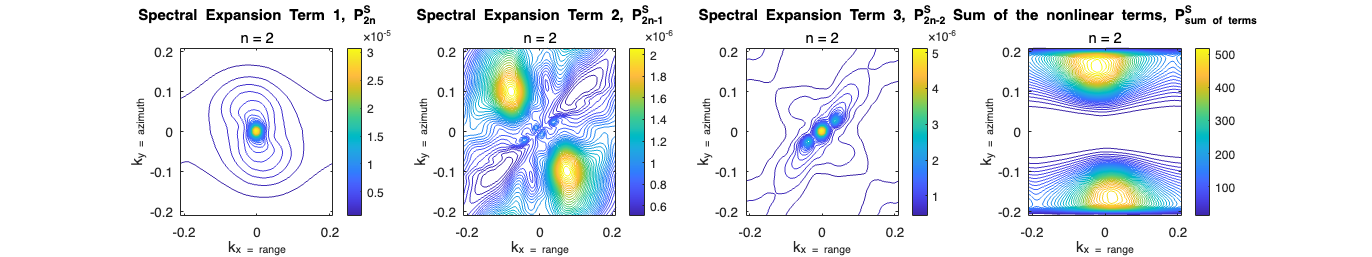

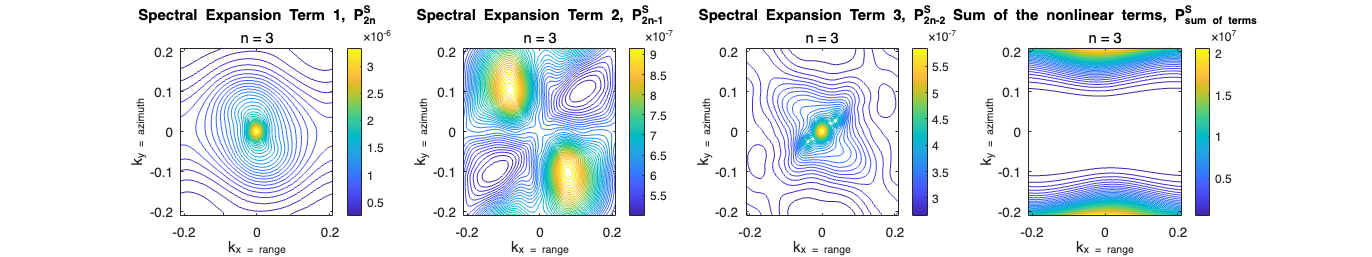

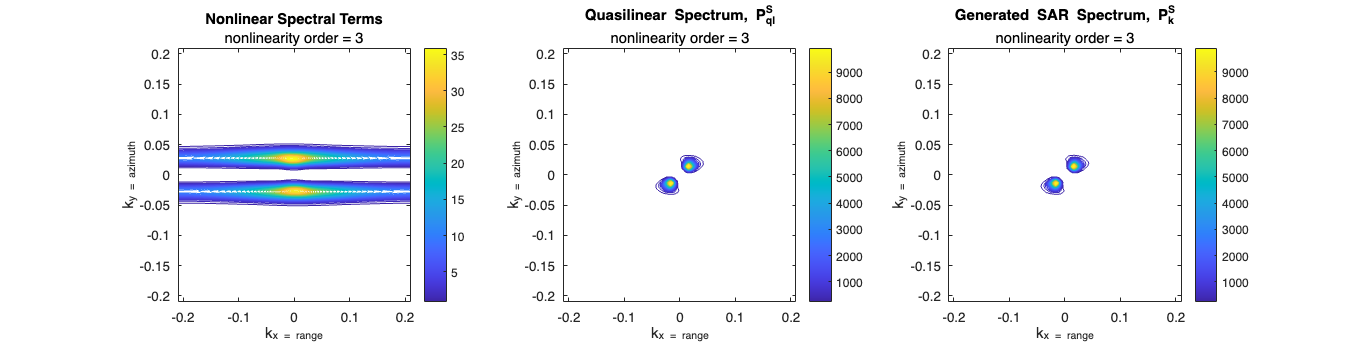

% Initialize variables (assuming they are defined elsewhere in your script)
lin_ord = 3;
first_guess_sar_spectrum = handh.sarImageVarianceSpectrumNonlinearMappingTransform(1, lin_ord, PS_ql, first_guess_ky_azimuth, sar_beta, fv_r, fRv_r, fR_r,xi_sqr, first_guess_kx_range);

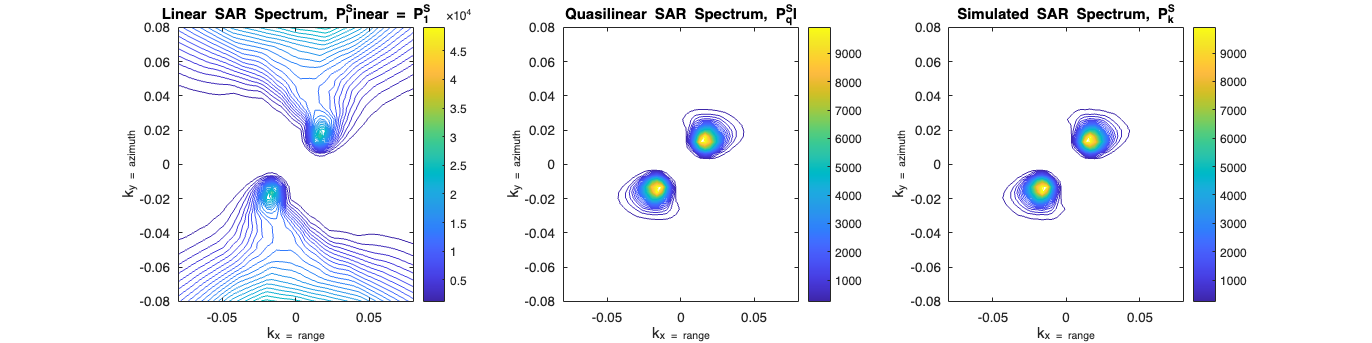

% dk = (sar_dy / (sar_sub_transect_size*2*pi))^2; % [Eq.45, H&H 1991]
dk = 1;

% Plot all components together
% TO DO: PLOT ALL PS_1, PS_ql, PS_k altogether.
figure('Position', [100, 100, 1200, 300]);
subplot(1,3,1);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(PS_1.*dk),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Linear SAR Spectrum, P^S_linear = P^S_1"); colorbar;
subplot(1,3,2);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(PS_ql.*dk),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Quasilinear SAR Spectrum, P^S_ql"); colorbar;
subplot(1,3,3);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(first_guess_sar_spectrum.*dk),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Simulated SAR Spectrum, P^S_k"); colorbar;

This code is a sanity check to compare the wavelength of the wave spectrum to that of the SAR spectrum. ****TODO**: move this somewhere else

% ps_k_nl = ps_k_nl / max(ps_k_nl(:)) * max(cross_spec(:));

% [temp1, temp2] = find(interp_E_kx_ky==max(interp_E_kx_ky(:)));
% k0 = first_guess_k(temp1,temp2);
% peak_wave_length_Ek = 2*pi/k0;

## 3 Observed SAR spectrum

- Subdivide the 512x512 transect into 16 128x128 sub transects

- For each sub transect: filter, normalise, fft

- Take the average of these sub transects

- Need to filter out the low frequencies using butterworth filter applied to covariance function and then ifft back to the spectrum

[observed_sar_spectrum_without_butterworth_gaussian] = observedSARSpectrum(sar_transect, sar_transect_size, sar_sub_transect_size, sar_dx, first_guess_k, 1, 1, -1);

% Using the Butterworth filter
cutoff = 500; % This is dependent on the sea state and used to remove the low frequencies. Maybe see if 2 * swell will work.
[observed_sar_spectrum_with_butterworth_without_gaussian] = observedSARSpectrum(sar_transect, sar_transect_size, sar_sub_transect_size, sar_dx, first_guess_k, 1, 1, cutoff);
% Using the Gaussian smoothing filter
size_of_filter_window = 5; % The number of elements = dim_filt + 1
width_of_gaussian_lobe = 2; % width_of_gaussian_lobe: Controls the spread of the Gaussian. A larger width means the Gaussian will be wider and smoother.
[observed_sar_spectrum] = observedSARSpectrum(sar_transect, sar_transect_size, sar_sub_transect_size, sar_dx, first_guess_k, size_of_filter_window, width_of_gaussian_lobe, cutoff);

% figure('Position', [100, 100, 1200, 600]);
% subplot(2,3,1);
% contour(first_guess_kx_range, first_guess_ky_azimuth, abs(observed_sar_spectrum_without_butterworth_gaussian),40);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("SAR Spectrum, P^S_{obs}","without Butterworth cutoff and Gaussian Filter ");
% c = colorbar();c.Label.String = 'Linear Scale'; grid on;
% subplot(2,3,2);
% contour(first_guess_kx_range, first_guess_ky_azimuth, abs(observed_sar_spectrum_with_butterworth_without_gaussian),40);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("SAR Spectrum, P^S_{obs}", "with Butterworth cutoff = 500, without Gausian filter ");
% c = colorbar();c.Label.String = 'Linear Scale'; grid on;
% subplot(2,3,3);
% contour(first_guess_kx_range, first_guess_ky_azimuth, abs(observed_sar_spectrum),40);
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("SAR Spectrum, P^S_{obs}", "with Butterworth cutoff = 500 and Gausian filter dim = 6, width = 3 ");
% c = colorbar();c.Label.String = 'Linear Scale'; grid on;
% subplot(2,3,4);
% contour(first_guess_kx_range, first_guess_ky_azimuth, 20*log10(abs(observed_sar_spectrum_without_butterworth_gaussian)));
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("SAR Spectrum, P^S_{obs}","without Butterworth cutoff and Gaussian Filter ");
% c = colorbar();c.Label.String = 'dB Scale'; grid on;
% subplot(2,3,5);
% contour(first_guess_kx_range, first_guess_ky_azimuth, 20*log10(abs(observed_sar_spectrum_with_butterworth_without_gaussian)));
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("SAR Spectrum, P^S_{obs}", "with Butterworth cutoff = 500, without Gausian filter ");
% c = colorbar();c.Label.String = 'dB Scale'; grid on;
% subplot(2,3,6);
% contour(first_guess_kx_range, first_guess_ky_azimuth, 20*log10(abs(observed_sar_spectrum)));
% xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("SAR Spectrum, P^S_{obs}", "with Butterworth cutoff = 500 and Gausian filter dim = 6, width = 3 ");
% c = colorbar();c.Label.String = 'dB Scale'; grid on;

### Plot the observed and simulated spectra together

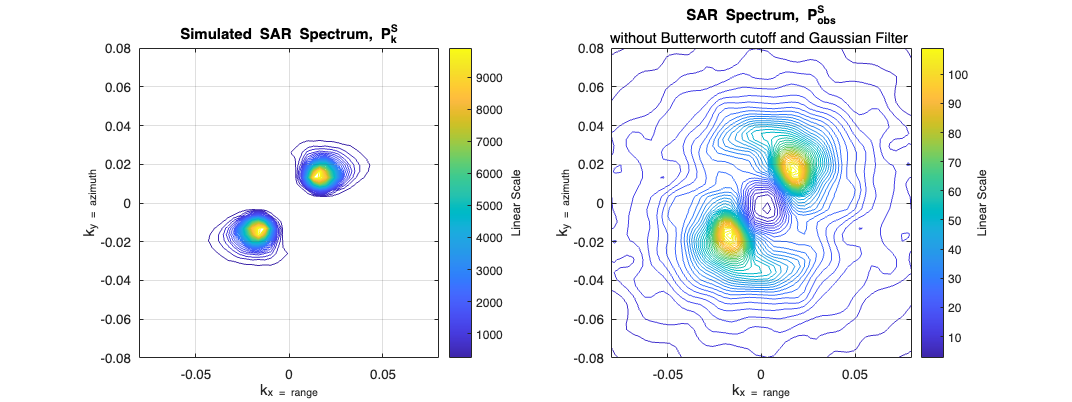

figure('Position', [100, 100, 800, 300]);
subplot(1,2,1);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(first_guess_sar_spectrum),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Simulated SAR Spectrum, P^S_k"); 
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
subplot(1,2,2);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(observed_sar_spectrum),40);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("SAR Spectrum, P^S_{obs}","without Butterworth cutoff and Gaussian Filter ");
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
xlim([-0.08 0.08]); ylim([-0.08 0.08]);

## 4 Inversion

### 4.0 General variables

handh = hAndH1991Functions;
transect_number = 1; % This will mainly be used when looping through all transects in the ice part of the pipeline

nonlinearity_order = 3;
inversion_iterations = 10;
P_obs = observed_sar_spectrum;
F_era5_k = first_guess_wave_number_spectrum;
P_era5_k = first_guess_sar_spectrum;

kx = first_guess_kx_range(1,:); % This is required for integration
ky = first_guess_ky_azimuth(:,1); % This is required for integration

***PROBLEM:***

***This seems to be a bug... not sure where it is caused.***

ky = flipud(ky);

iteration 1,1,1
iteration 1,1,5
iteration 1,1,9
iteration 1,1,13
iteration 1,1,14
iteration 1,1,15
iteration 1,1,16
iteration 1,1,17
iteration 1,1,18
iteration 1,1,29
iteration 1,1,30
iteration 1,1,31


The above additional step is required to ensure that the values returned in the cost function are positive. When this step is used, kx and ky are both linearly ascending rather than ky ascending and kx descending (seen when plotting the variables). When they are opposite, the integration in the cost function equations result in a negative output rather than a positive value. Therefore, the kx variable is flipped so that it is identical to ky. 

My only concern here is that the kx and ky matrices do not look the same because we are dealing with a right-looking SAR. As per the definition in H&H, for a right looking SAR ky = -1 ky. That is why kx and ky are not identical. Does making them identical here effect anything?

### 4.1 Step Zero

- "Step zero" as Giacomo calls it

- Page 10,723 of H&H 1991

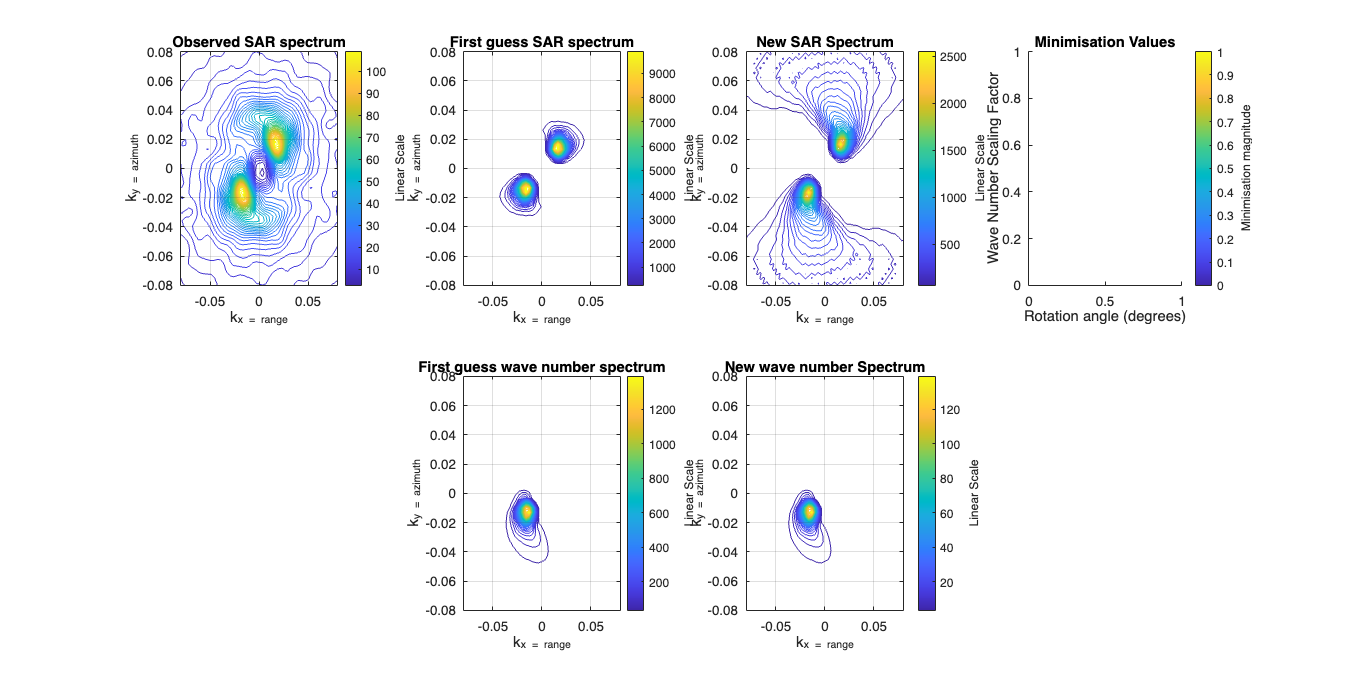

[J_step0,S_new, P_new, energy_0_i,new_kx_0,new_ky_0,rot_angle_0] = inversionStep0(nonlinearity_order, 0,transect_number, P_obs, first_guess_wave_number_spectrum,kx,ky,first_guess_omega,first_guess_k,sar_sub_transect_size, cosmo, handh);
figure('Position', [100, 100, 1200, 600]);
subplot(2,4,1);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(P_obs),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Observed SAR spectrum"); 
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
subplot(2,4,2);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(first_guess_sar_spectrum),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("First guess SAR spectrum"); 
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
subplot(2,4,3);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(P_new),40);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("New SAR Spectrum");
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
subplot(2,4,4); 
clear temp;
% temp(:,:) = J_step0(energy_0_i,:,:);
% pcolor(temp); 
title("Minimisation Values"); ylabel("Wave Number Scaling Factor"); xlabel("Rotation angle (degrees)"); c = colorbar(); c.Label.String = 'Minimisation magnitude';
% subplot(2,4,5);
subplot(2,4,6);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(first_guess_wave_number_spectrum),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("First guess wave number spectrum"); 
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
subplot(2,4,7);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(S_new),40);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("New wave number Spectrum");
c = colorbar();c.Label.String = 'Linear Scale'; grid on;

xlim([-0.08 0.08]); ylim([-0.08 0.08]);
% subplot(2,4,8);

### 4.2 Inversion: Eq 62, 63 & 69   

% F_era5_k = S_new;
% kx = new_kx(1,:); % This is required for integration
% ky = new_ky(:,1); % This is required for integration

[J_eq_62,P_best_eq62,F_best_eq62,J_eq_63,P_best_eq63,F_best_eq63,J_eq_69,P_best_eq69,F_best_eq69] = inversionHH(inversion_iterations, nonlinearity_order, cosmo, handh, 0, P_obs, F_era5_k,transect_number, sar_sub_transect_size, first_guess_kx_range, first_guess_ky_azimuth, first_guess_omega, first_guess_k , Tv_k, sar_beta, TS_k);


Eq62: iteration 1
Eq63: iteration 1
Eq96: iteration 1
Eq62: iteration 2
Eq63: iteration 2
Eq96: iteration 2
Eq62: iteration 3
Eq63: iteration 3
Eq96: iteration 3
Eq62: iteration 4
Eq63: iteration 4
Eq96: iteration 4
Eq62: iteration 5
Eq63: iteration 5
Eq96: iteration 5
Eq62: iteration 6
Eq63: iteration 6
Eq96: iteration 6
Eq62: iteration 7
Eq63: iteration 7
Eq96: iteration 7
Eq96: iteration 8


figure('Position', [100, 100, 1200, 900]);
subplot(3,3,1);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(F_best_eq62),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final Wave Spectrum, F_k","From Eq.62 Inversion"); 
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
subplot(3,3,2);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(P_best_eq62),40);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final SAR Spectrum, P^S_{k}","From Eq.62 Inversion");
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
subplot(3,3,3);
plot(J_eq_62); xticks((1:1:inversion_iterations)); xlabel("Number of iterations");

subplot(3,3,4);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(F_best_eq63),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final Wave Spectrum, F_k","From Eq.63 Inversion"); 
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
subplot(3,3,5);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(P_best_eq63),40);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final SAR Spectrum, P^S_{k}","From Eq.63 Inversion");
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
subplot(3,3,6);
plot(J_eq_63); xticks((1:1:inversion_iterations)); xlabel("Number of iterations");

subplot(3,3,7);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(F_best_eq69),40);
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final Wave Spectrum, F_k","From Eq.69 Inversion"); 
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
subplot(3,3,8);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(P_best_eq69),40);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final SAR Spectrum, P^S_{k}","From Eq.69 Inversion");
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
subplot(3,3,9); 
plot(J_eq_69); xticks((1:1:inversion_iterations)); xlabel("Number of iterations");

### 4.3 Giacomo's Inversion

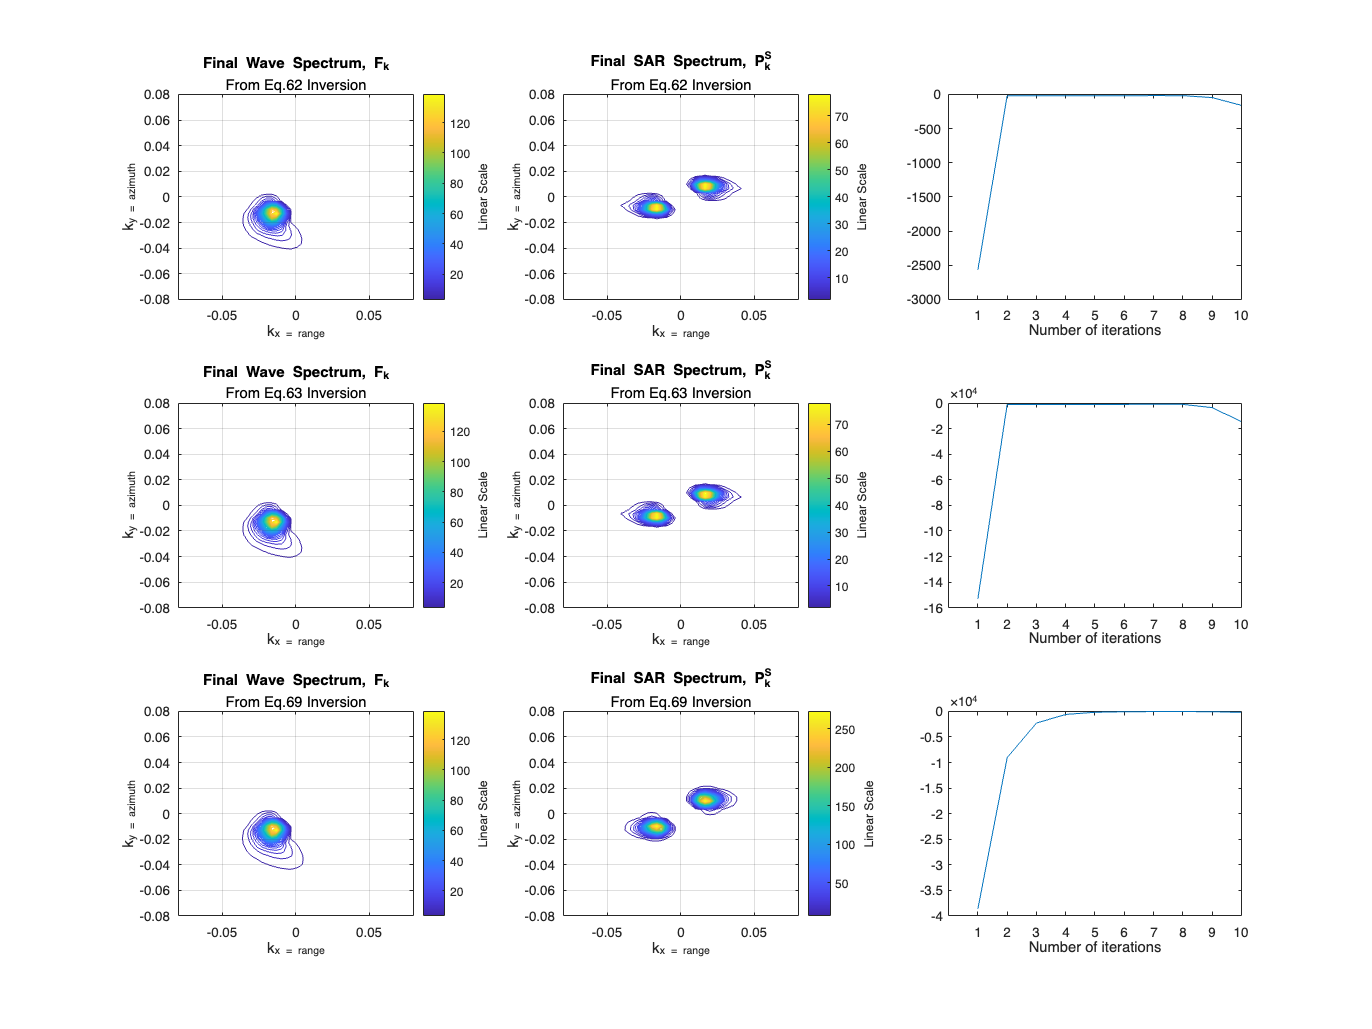

[F_best_giacomo_eps, P_best_giacomo_eps, eps, F_best_giacomo_J, P_best_giacomo_J, J] = inversionGiacomo(inversion_iterations, nonlinearity_order, F_era5_k, P_obs, TS_k, first_guess_ky_azimuth ,first_guess_kx_range,xi_sqr, first_guess_omega, cosmo,first_guess_k,transect_number,sar_sub_transect_size, handh);

figure('Position', [100, 100, 1200, 600]);
subplot(2,3,1);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(F_best_giacomo_J));

    "EPS iteration 1"

    "J iteration 1"

    "EPS iteration 2"

    "J iteration 3"

    "J iteration 6"

    "EPS iteration 10"



xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final Wave Spectrum, F_k","From Giacomo J Inversion"); 
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
subplot(2,3,2);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(P_best_giacomo_J),40);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final SAR Spectrum, P^S_{k}","From Giacomo J Inversion");
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
subplot(2,3,3);
plot(J); xticks((1:1:inversion_iterations)); xlabel("Number of iterations"); 


subplot(2,3,4);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(F_best_giacomo_eps));
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final Wave Spectrum, F_k","From Giacomo eps Inversion"); 
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
subplot(2,3,5);
contour(first_guess_kx_range, first_guess_ky_azimuth, abs(P_best_giacomo_eps),40);
xlabel("k_{x = range}"); ylabel("k_{y = azimuth}"); title("Final SAR Spectrum, P^S_{k}","From Giacomo eps Inversion");
c = colorbar();c.Label.String = 'Linear Scale'; grid on;
xlim([-0.08 0.08]); ylim([-0.08 0.08]);
subplot(2,3,6);
plot(eps); xticks((1:1:inversion_iterations)); xlabel("Number of iterations");

Check the outputs of the best fit compared to the original and observed spectra. Will need to do this for the buoy data to compare the results.

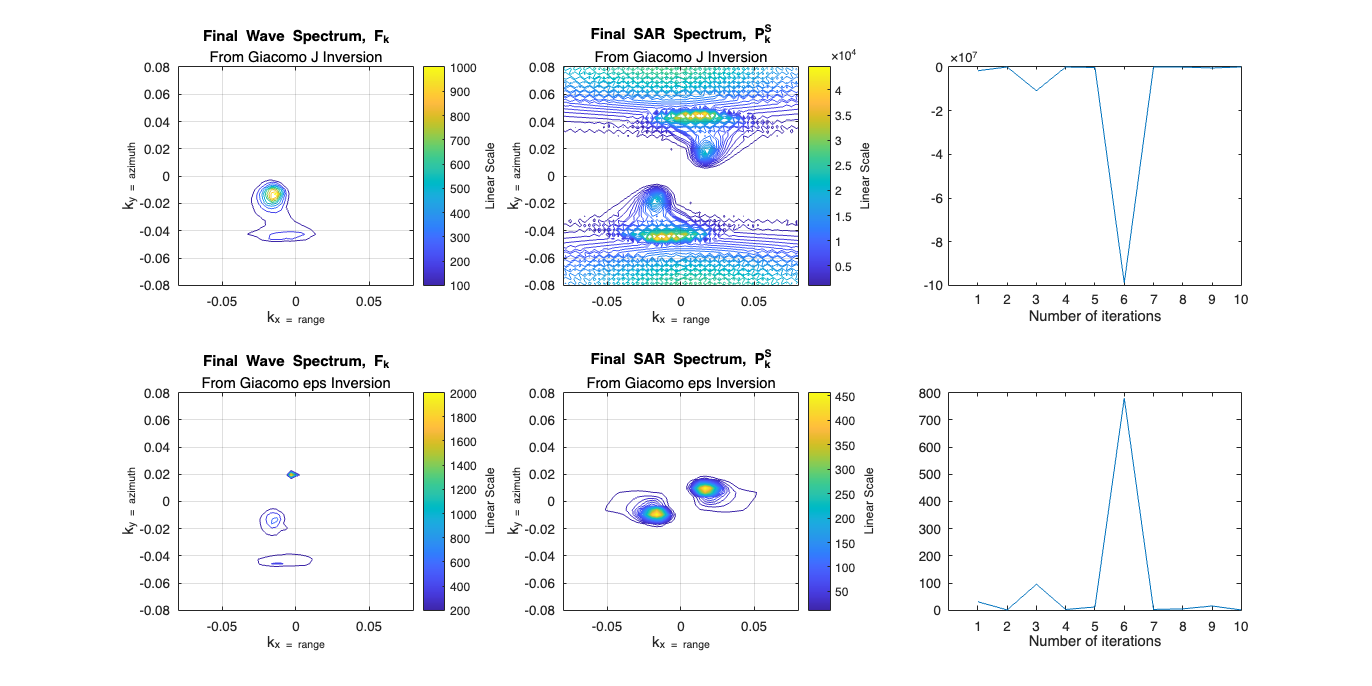

clear k0;
%% WAVE SPECTRA
% ps_k_nl = ps_k_nl / max(ps_k_nl(:)) * max(cross_spec(:));

[temp1, temp2] = find(first_guess_wave_number_spectrum==max(first_guess_wave_number_spectrum(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Fk_First_guess = 2*pi/k0
[temp1, temp2] = find(F_best_giacomo_eps==max(F_best_giacomo_eps(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Fk_giacomo_eps = 2*pi/k0
[temp1, temp2] = find(F_best_giacomo_J==max(F_best_giacomo_J(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Fk_giacomo_J = 2*pi/k0

%% SAR SPECTRA
[temp1, temp2] = find(first_guess_sar_spectrum==max(first_guess_sar_spectrum(:)));
k0 = first_guess_k(temp1,temp2)
% peak_wave_length_Pk_first_guess = 2*pi/k0
[temp1, temp2] = find(observed_sar_spectrum==max(observed_sar_spectrum(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Pk_obs = 2*pi/k0
[temp1, temp2] = find(P_best_giacomo_eps==max(P_best_giacomo_eps(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Pk_giacomo_eps = 2*pi/k0

[temp1, temp2] = find(P_best_giacomo_J==max(P_best_giacomo_J(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Pk_giacomo_J = 2*pi/k0

# Sea Ice Section

NOT WORKING ON THIS FOR NOW

## 1 Transects

Here we need to figure out the mean wave direction and take the transects along this for the ice part of the pipeline.

### 3.5 Calculate the parameters for the data located at specified latitude, longitude and specified time

These equations are taken from ?

% % Calculate the wave spectrum for all time
% era5_d2fd_all_time = zeros(size(era5_d2fd_all,5),size(era5_d2fd_all,3),size(era5_d2fd_all,4)); % dimensions t direc freq
% for t = 1:size(era5_d2fd_all,5)
%     era5_d2fd_match(:,:) = era5_d2fd_all(lon_position_match,lat_position_match,:,:,t); % Dimensions are: direction,frequency
%     era5_d2fd_all_time(t,:,:) = 10.^era5_d2fd_match;
%     era5_d2fd_all_time(isnan(era5_d2fd_all_time))=0; % Otherwise all values are just N
% end

#### Significant Wave Height

% Calculate the 0th order moments (m_n) [Eq.8]
era5_m0_derived = trapz(era5_direction_bins_degrees,trapz(era5_freq_bins,1*era5_d2fd,1),2); %[Eq.8], dimension 2,3 = direc,freq
% era5_m0_derived_all_time = trapz(era5_direction_bins,trapz(era5_freq_bins,1*era5_d2fd_all_time,3),2); %[Eq.8], dimension 2,3 = direc,freq

% Calculate the significant wave height (Hs) [Eq.4]
era5_Hs_derived = 4*sqrt(era5_m0_derived);
% era5_Hs_derived_all_time = 4*sqrt(era5_m0_derived_all_time);

#### Mean Wave period

% Calculate the -1st order moments (m_n)
era5_m_neg1_derived = trapz(era5_direction_bins_degrees,trapz(era5_freq_bins,(1./era5_freq_bins).*era5_d2fd,1),2); %[Eq.8]
% era5_m_neg1_derived_all_time = zeros(size(era5_d2fd_all,5),1);
% for t = 1:size(era5_d2fd_all,5)
%     spectrum(:,:) = era5_d2fd_all_time(t,:,:);
%     era5_m_neg1_derived_all_time(t,1) = trapz(era5_direction_bins,trapz(era5_freq_bins,(1/era5_freq_bins).*era5_spectrum_all_time,2),1); %[Eq.8]
% end

% Calculate the mean wave period (Tm) [Eq.5]
era5_Tm_derived = era5_m_neg1_derived/era5_m0_derived; % [Eq.5]
% era5_Tm_derived_all_time = era5_m_neg1_derived_all_time./era5_m0_derived_all_time; % [Eq.5]

#### Mean Wave direction

% Calculate the angular moments [Eq.9&10]
era5_a1 = trapz(era5_freq_bins,trapz(era5_direction_bins_degrees,cos(era5_direction_bins_degrees).*era5_d2fd,2),1); %[Eq.9]
era5_b1 = trapz(era5_freq_bins,trapz(era5_direction_bins_degrees,sin(era5_direction_bins_degrees).*era5_d2fd,2),1); %[Eq.10]
% for t = 1:size(era5_d2fd_all,5)
%     spectrum(:,:) = era5_d2fd_all_time(t,:,:); % dimenstions: direc, freq
%     era5_a1_all_time(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,cos(era5_direction_bins)'.*era5_spectrum_all_time,1),2); %[Eq.9]
%     era5_b1_all_time(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,sin(era5_direction_bins)'.*era5_spectrum_all_time,1),2); %[Eq.10]
% end

% Calculate the mean Direction of the wave
era5_direction_derived = atand(era5_b1./era5_a1); %[Eq.6]
era5_direction_derived_radians = era5_direction_derived * pi/180;
% era5_direction_derived_all_time = atand(era5_b1_all_time./era5_a1_all_time); %[Eq.6]

#### **Spectral Denisty**

% Total variance/energy of the waves = spectral density integrated over all
% frequencies and wave numbers at specified time of interest
% total_variance_or_energy = trapz(trapz(era5_d2fd,2),1);

### 2.7 Plot Mean Wave Direction

% Plot the Lat-Long x-y grid
[era5_lonGrid, era5_latGrid] = meshgrid(era5_lon,era5_lat);

% Plot the grid (optional, for context)
figure;
plot(era5_lonGrid, era5_latGrid, "k+");  % Plot grid points for reference
hold on;
% Plot the directional arrow at the specific latitude and longitude
quiver(longitude_of_interest, latitude_of_interest, cos(era5_direction_derived_radians), sin(era5_direction_derived_radians), ...
    'AutoScale', 'off', 'MaxHeadSize', 2, 'LineWidth', 2, 'Color', 'r');

% Adjust plot settings
title('Directional Arrow at Specific Location of Wave Spectrum');
xlabel('Longitude'); ylabel('Latitude');
axis equal;  % Ensure equal scaling of axes
grid on;
grid minor;
hold off;